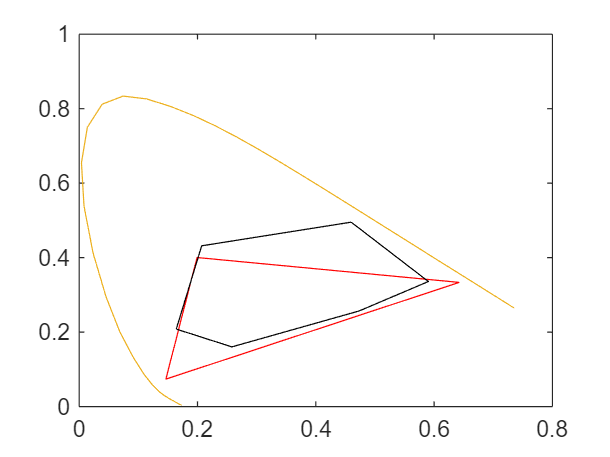

%1
clear
load("Dell.mat")
load("Inkjet.mat")

hold off
plot_chrom(XYZdell,"r") %r, red
plot_chrom(XYZinkjet,"k")%k is black in cmyk

Inkjet covers a somewhat larger area in general but misses some of the reds and blues that dell covers, mainly blue though.

%2.1.1
clear
%Load with imread and immediately convert to double
grayPeppers=im2double(imread("peppers_gray.tif"));
save("grayPeppers","grayPeppers")

%Img resizing
nearestGrayPeppers=imresize(imresize(grayPeppers,0.25,"nearest"),4,"nearest");
bilinearGrayPeppers=imresize(imresize(grayPeppers,0.25,"bilinear"),4,"bilinear");
bicubicGrayPeppers=imresize(imresize(grayPeppers,0.25,"bicubic"),4,"bicubic");

%SNR Calc
"SNR"

ans = "SNR"

snr(grayPeppers,nearestGrayPeppers)

ans = -0.0301

mysnr(grayPeppers,nearestGrayPeppers)

ans = -0.0301


snr(grayPeppers,bilinearGrayPeppers)

ans = 0.1127

mysnr(grayPeppers,bilinearGrayPeppers)

ans = 0.1127


snr(grayPeppers,bicubicGrayPeppers)

ans = 0.0615

mysnr(grayPeppers,bicubicGrayPeppers)

ans = 0.0615


%MSE Calc
"MSE"

ans = "MSE"

immse(nearestGrayPeppers,grayPeppers)

ans = 0.0043

immse(bilinearGrayPeppers,grayPeppers)

ans = 0.0028

immse(bicubicGrayPeppers,grayPeppers)

ans = 0.0023

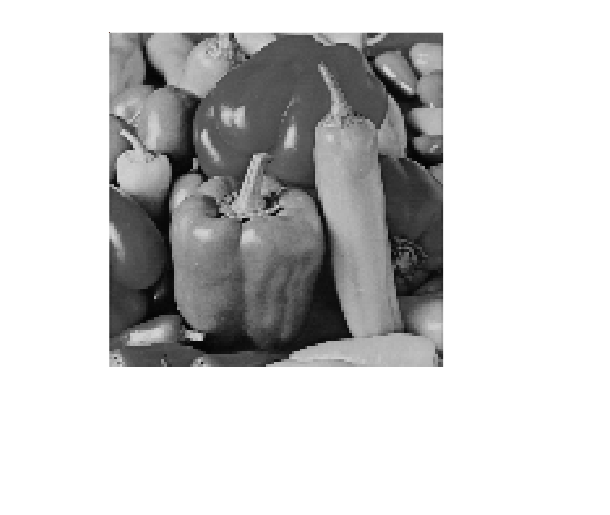


%Visual comparison
imshow(nearestGrayPeppers)

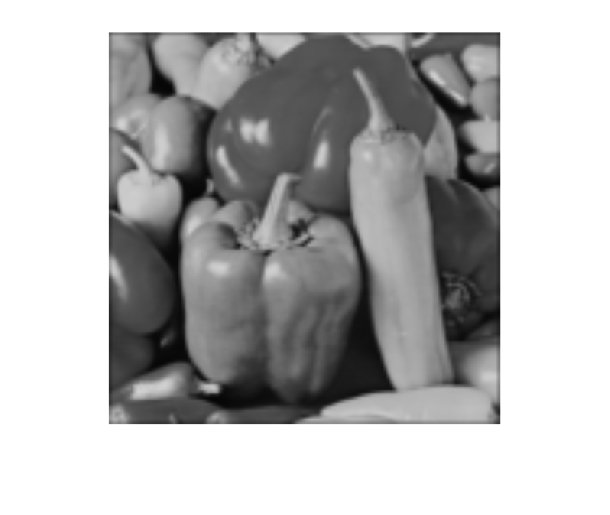

imshow(bilinearGrayPeppers)

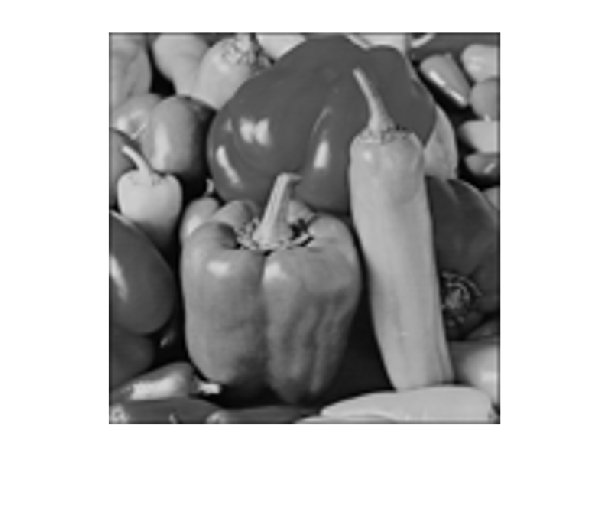

imshow(bicubicGrayPeppers)

Bicubic is visually the best representation.

MSE agrees, but SNR (which is better the closer to 1) would argue it's Bilinear.

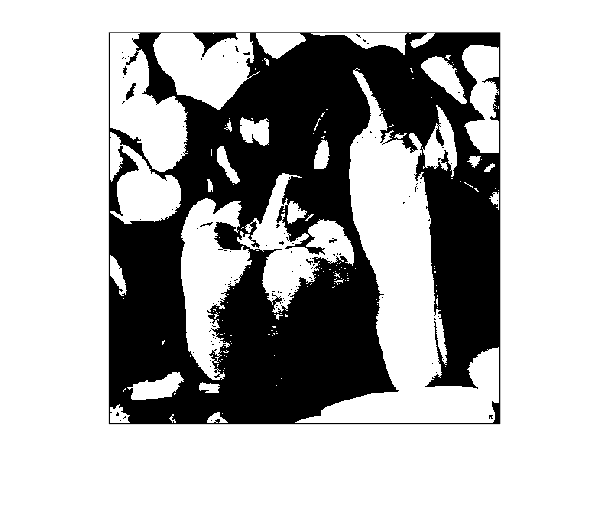

%2.1.2
%imThresh=double(grayPeppers>=0.65);
imThresh=double(grayPeppers>=0.5);
save("imThresh","imThresh");
imshow(imThresh)

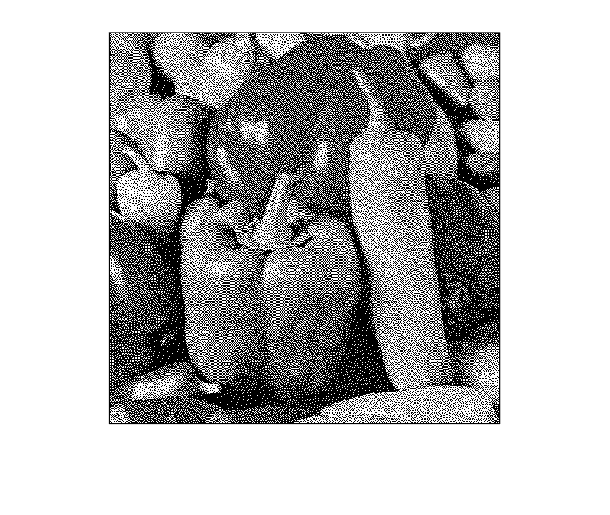


imDither=double(dither(grayPeppers));
save("imDither","imDither");
imshow(imDither)


snr(imDither,grayPeppers)

ans = 2.8185

snr(imThresh,grayPeppers)

ans = 2.5967

immse(imDither,grayPeppers)

ans = 0.2004

immse(imThresh,grayPeppers)

ans = 0.1111


snr(grayPeppers,imThresh)

ans = -2.5967

snr(grayPeppers,imDither)

ans = -2.8185

According to mse imdither is further from truth, but visually this is false.

SNR identifies this with a higher score. Unsure how the SNR scoring works.. in lecture good SNR was ~1 but now snr can go to 6??? 0.65 thresholding gave ~1

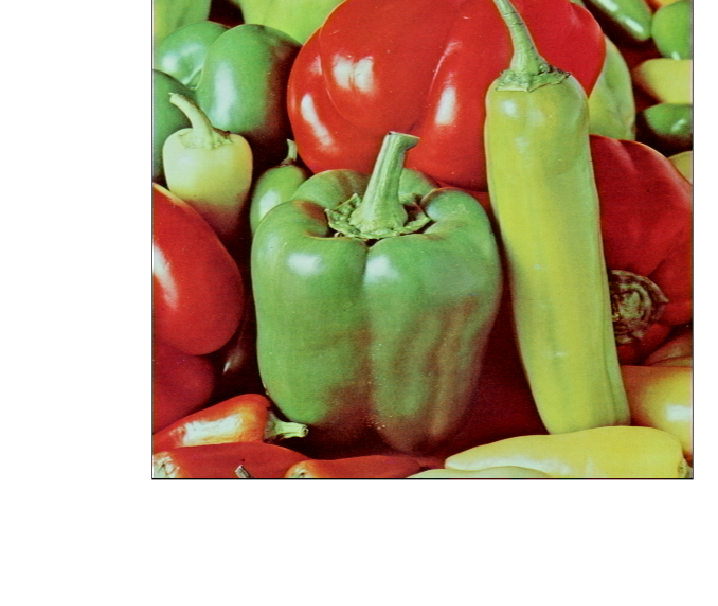

%2.2
clear
%Load RGB image
colorPeppers=im2double(imread("peppers_color.tif"));
imshow(colorPeppers)

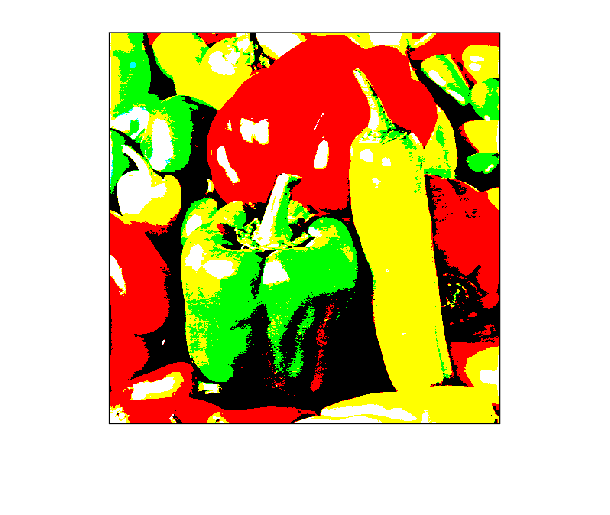


%Half-tone channels by thresholding
htTHColorPeppers=cat(3,double(colorPeppers(:,:,1)>=0.5),double(colorPeppers(:,:,2)>=0.5),double(colorPeppers(:,:,3)>=0.5));
imshow(htTHColorPeppers)

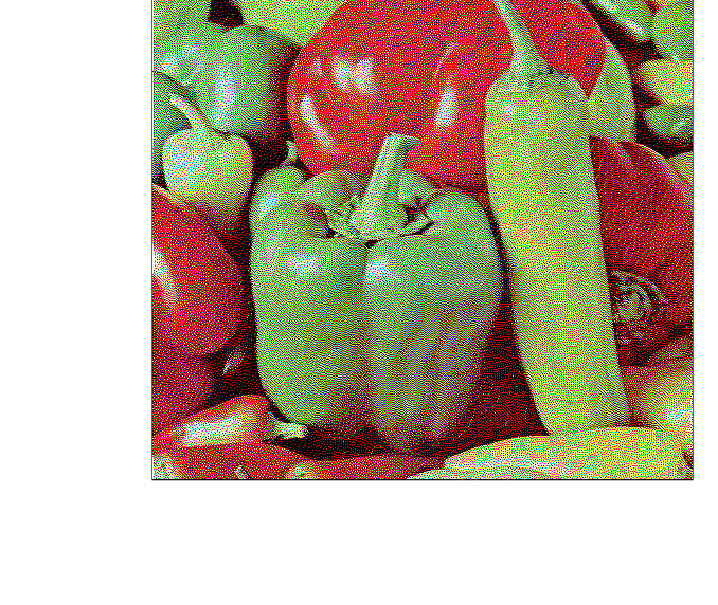


%Dither half-toning
htDTColorPeppers=cat(3,double(dither(colorPeppers(:,:,1))),double(dither(colorPeppers(:,:,2))),double(dither(colorPeppers(:,:,3))));
imshow(htDTColorPeppers)


%Convert to Lab
labPeppers=rgb2lab(colorPeppers);
labhtTHPeppers=rgb2lab(htTHColorPeppers);
labhtDTPeppers=rgb2lab(htDTColorPeppers);
immse(labhtDTPeppers,labPeppers)

ans = 2.2208e+03

immse(labhtTHPeppers,labPeppers)

ans = 944.7638


snr(labhtDTPeppers,labPeppers)

ans = 3.3925

snr(labhtTHPeppers,labPeppers)

ans = 3.6015

MSE puts the thresholded image as WILDLY of, sure it's not super accurate but it's definately not THAT bad. SNR puts them as somewhat equal, with dither being slightly better which i would agree on.

%3.1
clear
load("imDither.mat")
load("imThresh.mat")
load("grayPeppers.mat")

ditherNoise=grayPeppers-imDither;
threshNoise=grayPeppers-imThresh;
imshow(imDither)

snr_filter(imDither,ditherNoise)

ans = 13.5280

imshow(imThresh)

snr_filter(imThresh,threshNoise)

ans = 5.8391

If higher snr is better then it would correctly identify now that the dither representations is better.

%3.2
clear
colorPeppers=im2double(imread("peppers_color.tif"));
labPeppers=rgb2lab(rgb_filter(colorPeppers));

%Remake the half-toning but now apply filter before Lab
%Half-tone channels by thresholding
htTHColorPeppers=cat(3,double(colorPeppers(:,:,1)>=0.5),double(colorPeppers(:,:,2)>=0.5),double(colorPeppers(:,:,3)>=0.5));
imshow(htTHColorPeppers)

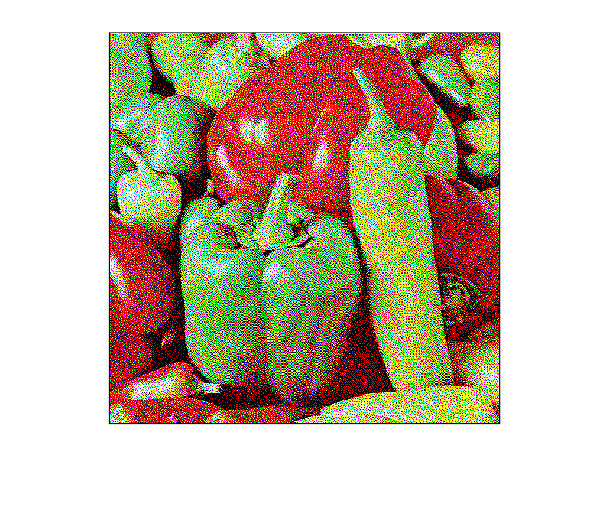


%Dither half-toning
htDTColorPeppers=cat(3,double(dither(colorPeppers(:,:,1))),double(dither(colorPeppers(:,:,2))),double(dither(colorPeppers(:,:,3))));
imshow(htDTColorPeppers)


%Convert to Lab & apply filter
labhtTHPeppers=rgb2lab(rgb_filter(htTHColorPeppers));
labhtDTPeppers=rgb2lab(rgb_filter(htDTColorPeppers));
"Dither"

ans = "Dither"

immse(labhtDTPeppers,labPeppers)

ans = 176.7340

"Threshold"

ans = "Threshold"

immse(labhtTHPeppers,labPeppers)

ans = 865.1154

MSE still thinks dither is the best representation but it likes it far less than previously.

%4
clear